Loading and processing the raw image

% Load and preprocess the image
img = imread("clemson.jpeg");

% Downsample the image to fit the matrix in memory
scaleFactor = 0.1; 
smallImage = imresize(img, scaleFactor);

% Convert to grayscale
img = rgb2gray(img); 
img = imresize(img, scaleFactor);
disp("Downsized Image Size: (Rows X Column)")

Downsized Image Size: (Rows X Column)


disp(size(img));

    96    96



Initializing the Adjacency Matrix

[rows, cols] = size(img);

% Hyperparameter for the gaussian similarity
sigma = 1; 

% Initializing the adjacency matrix
N = rows * cols;
adjMatrix = zeros(N, N);

% Construct the adjacency matrix
for i = 1:N
    for j = 1:N
        % Convert linear indices back to 2D indices
        [row_i, col_i] = ind2sub([rows, cols], i);
        [row_j, col_j] = ind2sub([rows, cols], j);

        xi = img(row_i, col_i);
        xj = img(row_j, col_j);

        % Calculating the Gaussian similarity
        similarity = exp(-sum((xi - xj) .^ 2) / (2 * sigma ^ 2));
        adjMatrix(i, j) = similarity;
    end
end

Calculating the Degree Matrix

% Construct the degree matrix
degreeMatrix = diag(sum(adjMatrix));

Calculating the Laplacian Matrix

laplacianMatrix = degreeMatrix - adjMatrix;

Calculate the eigenvectors

[eigVectors, eigValues] = eig(laplacianMatrix);

Performing K Means Clustering on the eigenVectors matrix

k = 2; % No of Clusters

eigVectors = eigVectors(:, 1:k);

% Normalizing Eigenvectors
rowNorms = sqrt(sum(eigVectors.^2, 2));
normalizedeigVectors = eigVectors ./ (rowNorms + eps);

clusters = kmeans(normalizedeigVectors, k);

% Reshape Clusters
segmentedImage = reshape(clusters, rows, []);

Displaying the Clustered Image

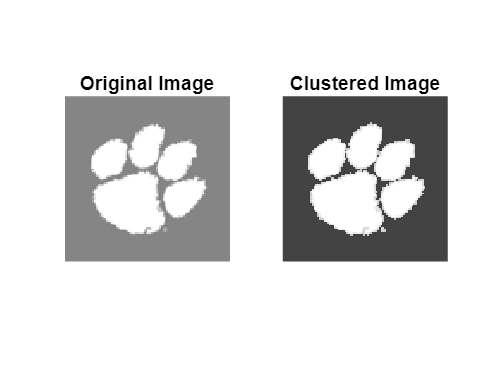

% Define a custom colormap for black and white
colormap = [0 0 0; 1 1 1]; % Black and White

% Create the overlay image using the custom colormap
newImage = labeloverlay(img, segmentedImage, 'Colormap', colormap);

% Display the original image and the black-and-white cluster overlay
figure;
subplot(1,2,1), imshow(img), title('Original Image');
subplot(1,2,2), imshow(newImage), title('Clustered Image');